# Random-walk maze runners

Lets create a large number of random-walking pixels, and define a boundary. When ANY pixel crosses that boundary, we want to stop executing the program and show the results (the winners walk, and all other walks). This winning pixel is the one which found the shortest path to the edge. Note: that is not the same as the shortest path possible, but it is a good approximation. 

Later, we can put some obstacle in the way and have them find the shortest path around these obstacles, and then extend that into a maze-solving program!

Create some code which holds the locations of a large number ( perhaps start with 300) of pixels and have them perform a random walk. When that random walk meets your success conditions

close all
mapheight=100;
mapwidth=100;
boundary=250;
map(1:300,1:300)=0;
stepsize=1;

walkers=20; %Define a number of particles
locations(1:walkers,1)=mapheight/2; %place them all at the centre of the map
locations(1:walkers,2)=mapwidth/2;
tracer=0;


set(figure, 'Visible', 'on')


i=0;
escaped=false;
while escaped==false
    i=i+1;
    step(1:walkers,1:2)=stepsize.*((rand(walkers,2)>=0.33).*((-1).^randi(2,walkers,2)));
    locations=locations+step;
    if any(locations(:,1)>mapwidth) | any(locations(:,2)>mapheight) | any(locations<0)
        escaped=true;
    end
    plot(locations(:,1),locations(:,2),'.')
    xlim([1, mapwidth])
    ylim([1, mapheight])
    drawnow
end
i



# Maze identifier

This will import your maze for solving.

maze = imread('maze.png')

Error using imread>get_full_filename (line 568)
File "maze.png" does not exist.

Error in imread (line 377)
    fullname = get_full_filename(filename);


hsvmaze = rgb2hsv(maze);
binmaze = hsvmaze(:,:,3) >= 0.3;

imshow(binmaze);
figure

## Find the start co-ordinate of you maze using the data cursor and write it below.

This command allows you to define a point from which the maze will start. Click a point.

imshow(binmaze)

Undefined function or variable 'binmaze'.

h = impoint;
coords=wait(h)


## Find the finish co-ordinate of your maze using the data cursor and write it below.

Two slightly different modes of succsessful completon are possible. When a maze is exited  through its periphery, and when some interior space is entered (such as a chest at the centre of a maze). The section below should account for both types.

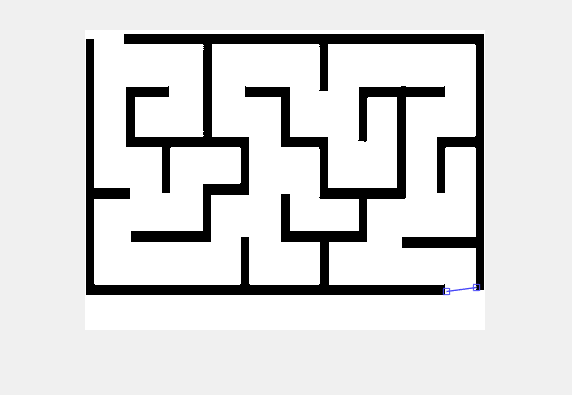

imshow(binmaze)
h = imline;

coords=wait(h)

coords =    362   262
   392   258


%End_co-ordinate = [1,1]


## find the height of you maze

this will determine height of your maze passages

imshow(binmaze)

Undefined function or variable 'binmaze'.

h = imline

coords = wait(h)

length = coords(2,2) - coords(1,2)

length = 42


round_length = round(length)

round_length = 42

%Better to use floor() and ceil(), depending on which margin you would rather err. (probably floor() )


## find the width of your maze

this will determine the width of your maze passages

imshow(binmaze)

Undefined function or variable 'binmaze'.

h = imline

coords = wait(h)

length = coords(2,1) - coords(1,1)

length = 31

%Better to use floor() and ceil(), depending on which margin you would rather err.
round_length = round(length)

round_length = 31

dfsfs

ds

dfsfs

ds

dfsfs

ds

dfsfs

ds

dfsfs

ds